clc
clear all
syms Omega k b m  a w_h_sq w_theta_sq x_theta_bar mu g_prime k Lh La Mh r_theta_bar_sq Ma 
b= 30;  %ft
m = 269.0; %slugs/ft
a = 0;
w_h = sqrt(0.775)  

w_h = 0.8803

w_theta = sqrt(2.41) 

w_theta = 1.5524

x_theta_bar = 0.0;
mu = 40.0;
% g_prime = 0;
k = 1./linspace(0.001,5.0,100)

k = 	1.0e+03 *

    1.0000    0.0194    0.0098    0.0066    0.0049    0.0039    0.0033    0.0028    0.0025    0.0022    0.0020    0.0018    0.0016    0.0015    0.0014    0.0013    0.0012    0.0012    0.0011    0.0010    0.0010    0.0009    0.0009    0.0009    0.0008    0.0008    0.0008    0.0007    0.0007    0.0007    0.0007    0.0006    0.0006    0.0006    0.0006    0.0006    0.0005    0.0005    0.0005    0.0005    0.0005    0.0005    0.0005    0.0005    0.0004    0.0004    0.0004    0.0004    0.0004    0.0004


1./k

ans =     0.0010    0.0515    0.1020    0.1525    0.2030    0.2535    0.3040    0.3545    0.4050    0.4555    0.5059    0.5564    0.6069    0.6574    0.7079    0.7584    0.8089    0.8594    0.9099    0.9604    1.0109    1.0614    1.1119    1.1624    1.2129    1.2634    1.3139    1.3644    1.4149    1.4654    1.5158    1.5663    1.6168    1.6673    1.7178    1.7683    1.8188    1.8693    1.9198    1.9703    2.0208    2.0713    2.1218    2.1723    2.2228    2.2733    2.3238    2.3743    2.4248    2.4753


r_theta_bar = sqrt(0.6222); %rtheta_bar^2
Mh = 0.5;
Ma = 3./8 -1i.*(1./k);
for n = 1:length(k)
ck = 1- ((0.165.*k(n))./(k(n)-0.0455.*1i))-((0.355.*k(n))./(k(n)-0.3.*1i));
Ma = 3./8 - 1i.*(1./k(n));
Lh = 1 - ((1i.*(2.*ck))./k(n));
La = 0.5 - ((1i.*(1+2.*ck))./k(n))-(2.*ck./(k(n)).^2);
A_b =  mu.*((1-Omega.*((w_h.^2)./(w_theta.^2))))+Lh;
B_b = (mu.*x_theta_bar)+ La - Lh.*(0.5+a);
D_b = (mu.*x_theta_bar)+ Mh - Lh.*(0.5+a);
E_b = (mu.*(r_theta_bar.^2)).*(1-Omega) - (Mh.*(0.5+a)) + Ma - La.*(0.5+a) + Lh.*((0.5+a).^2);
Eq = A_b.*E_b - B_b.*D_b;
omega(:,n) = eval(solve(Eq,Omega));
end
omega

omega =    1.0050 - 0.0000i   1.0051 - 0.0005i   1.0052 - 0.0011i   1.0055 - 0.0016i   1.0059 - 0.0021i   1.0063 - 0.0027i   1.0069 - 0.0033i   1.0076 - 0.0038i   1.0084 - 0.0044i   1.0093 - 0.0050i   1.0104 - 0.0057i   1.0115 - 0.0063i   1.0128 - 0.0070i   1.0141 - 0.0077i   1.0156 - 0.0084i   1.0173 - 0.0091i   1.0190 - 0.0099i   1.0209 - 0.0107i   1.0229 - 0.0115i   1.0250 - 0.0124i   1.0273 - 0.0133i   1.0297 - 0.0142i   1.0323 - 0.0151i   1.0350 - 0.0161i   1.0378 - 0.0171i   1.0408 - 0.0181i   1.0439 - 0.0191i   1.0472 - 0.0202i   1.0507 - 0.0213i   1.0543 - 0.0224i   1.0581 - 0.0236i   1.0621 - 0.0247i   1.0662 - 0.0259i   1.0705 - 0.0271i   1.0749 - 0.0283i   1.0796 - 0.0295i   1.0844 - 0.0307i   1.0894 - 0.0319i   1.0946 - 0.0331i   1.0999 - 0.0343i   1.1055 - 0.0355i   1.1112 - 0.0367i   1.1171 - 0.0379i   1.1233 - 0.0391i   1.1296 - 0.0402i   1.1361 - 0.0413i   1.1428 - 0.0424i   1.1497 - 0.0435i   1.1567 - 0.0445i   1.1640 - 0.0455i
   3.1874 - 0.0001i   3.1874 - 0.0038i   

w = w_theta./sqrt(real(omega))

w =     1.5485    1.5485    1.5484    1.5482    1.5479    1.5475    1.5471    1.5465    1.5459    1.5452    1.5444    1.5436    1.5426    1.5416    1.5404    1.5392    1.5379    1.5365    1.5350    1.5334    1.5317    1.5299    1.5280    1.5260    1.5239    1.5217    1.5194    1.5170    1.5145    1.5119    1.5092    1.5064    1.5035    1.5005    1.4973    1.4941    1.4908    1.4874    1.4838    1.4802    1.4765    1.4727    1.4688    1.4648    1.4607    1.4565    1.4522    1.4479    1.4434    1.4389
    0.8695    0.8695    0.8696    0.8696    0.8696    0.8697    0.8697    0.8698    0.8699    0.8700    0.8701    0.8702    0.8704    0.8705    0.8706    0.8708    0.8710    0.8711    0.8713    0.8715    0.8717    0.8719    0.8721    0.8723    0.8726    0.8728    0.8730    0.8733    0.8735    0.8738    0.8741    0.8743    0.8746    0.8749    0.8751    0.8754    0.8757    0.8760    0.8763    0.8766    0.8769    0.8772    0.8775    0.8778    0.8781    0.8784    0.8787    0.8790    0.8793    0

g = real(((w_theta.^2).*1i - omega.*(w.^2).*1i)./(w_theta.^2))

g =    -0.0000   -0.0005   -0.0011   -0.0016   -0.0021   -0.0027   -0.0032   -0.0038   -0.0044   -0.0050   -0.0056   -0.0062   -0.0069   -0.0076   -0.0083   -0.0090   -0.0097   -0.0105   -0.0113   -0.0121   -0.0129   -0.0138   -0.0146   -0.0155   -0.0165   -0.0174   -0.0183   -0.0193   -0.0203   -0.0213   -0.0223   -0.0233   -0.0243   -0.0253   -0.0263   -0.0273   -0.0283   -0.0293   -0.0302   -0.0312   -0.0321   -0.0330   -0.0339   -0.0348   -0.0356   -0.0364   -0.0371   -0.0378   -0.0385   -0.0391
   -0.0000   -0.0012   -0.0024   -0.0036   -0.0048   -0.0060   -0.0072   -0.0084   -0.0096   -0.0109   -0.0121   -0.0134   -0.0146   -0.0159   -0.0173   -0.0186   -0.0200   -0.0213   -0.0227   -0.0242   -0.0256   -0.0271   -0.0286   -0.0301   -0.0317   -0.0333   -0.0349   -0.0365   -0.0382   -0.0399   -0.0417   -0.0434   -0.0453   -0.0471   -0.0490   -0.0509   -0.0528   -0.0548   -0.0568   -0.0589   -0.0610   -0.0631   -0.0653   -0.0675   -0.0698   -0.0721   -0.0744   -0.0768   -0.0792   -0

V = w.*b./k

V =     0.0465    2.3922    4.7375    7.0822    9.4256   11.7677   14.1078   16.4457   18.7810   21.1133   23.4421   25.7672   28.0880   30.4041   32.7152   35.0208   37.3204   39.6137   41.9001   44.1792   46.4505   48.7136   50.9680   53.2132   55.4487   57.6740   59.8887   62.0922   64.2842   66.4640   68.6312   70.7854   72.9261   75.0528   77.1651   79.2625   81.3445   83.4109   85.4611   87.4948   89.5116   91.5111   93.4930   95.4570   97.4027   99.3299  101.2383  103.1276  104.9976  106.8482
    0.0261    1.3433    2.6606    3.9780    5.2955    6.6133    7.9313    9.2496   10.5683   11.8874   13.2070   14.5270   15.8476   17.1688   18.4906   19.8130   21.1362   22.4600   23.7846   25.1101   26.4363   27.7634   29.0913   30.4201   31.7498   33.0805   34.4121   35.7446   37.0781   38.4126   39.7480   41.0845   42.4220   43.7605   45.1000   46.4405   47.7820   49.1246   50.4682   51.8129   53.1585   54.5052   55.8529   57.2017   58.5515   59.9023   61.2541   62.6069   63.9607   65

plot(V(1,:),g(1,:),"ro")
hold on
Vf = interp1([-0.00161096 0.00139588],[162.133 163.357],0)

Vf = 162.7888

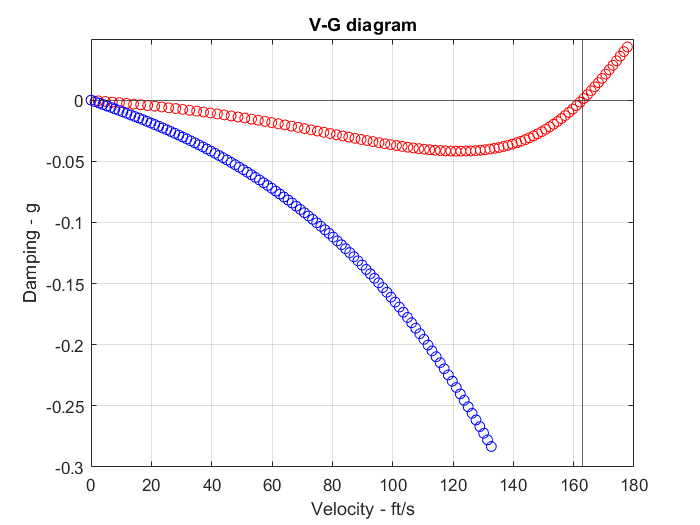

xline(Vf)
yline(0)
plot(V(2,:),g(2,:),"bo")
hold off
grid on
xlabel('Velocity - ft/s')
ylabel('Damping - g')
title('V-G diagram')

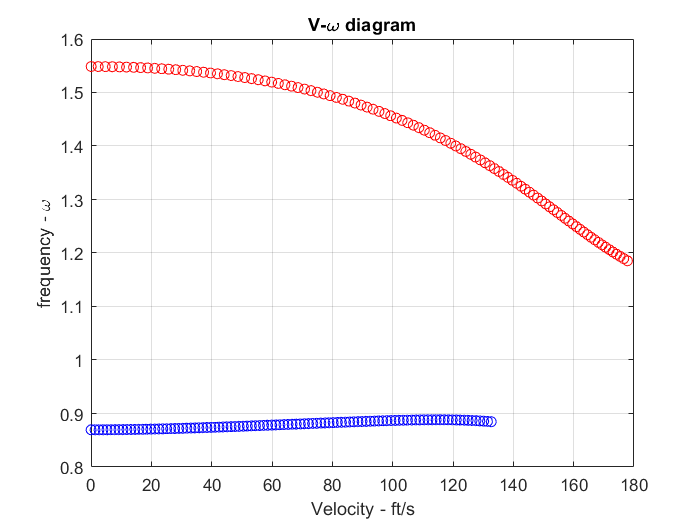

% plot(V(:,2),g(:,2))
plot(V(1,:),w(1,:),"ro")
hold on
plot(V(2,:),w(2,:),"bo")
title('V-\omega diagram')
xlabel('Velocity - ft/s')
ylabel('frequency - \omega')
grid on
hold off